# Estructuras de datos: Tablas

Las tablas son un tipo de datos adecuado para datos tabulares que a menudo se almacenan como columnas en un archivo de texto o en una hoja de cálculo. Las tablas constan de filas (**observaciones**) y columnas (**variables**).

**Figura 1.** Ilustración de una tabla en MATLAB.

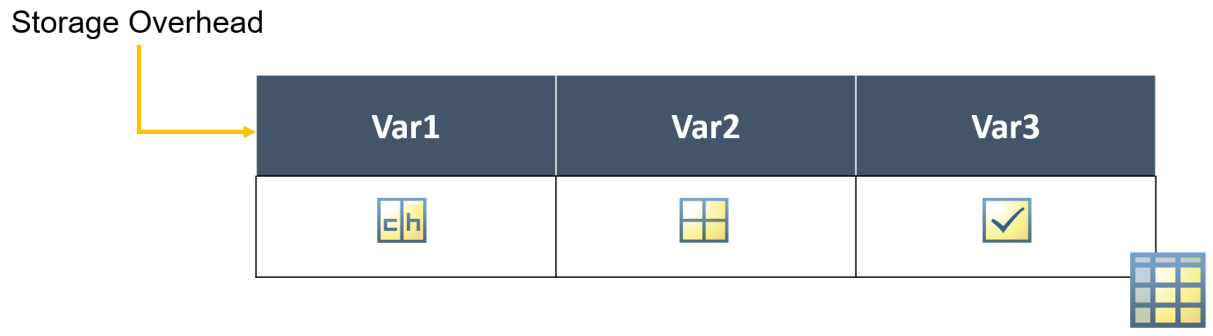

*Tomado de MATLAB Programming Techniques Quick Reference.*

**Cada variable en una tabla puede tener un tipo de datos diferente, la única restricción es que cada variable debe tener el mismo número de observaciones.**

Además, no está restringido que una variable sea de una sola columna. Es decir, una variable puede contener varias columnas, siempre y cuando todas estas tengan el mismo número de filas.

## Crear una tabla

Las tablas dentro de MATLAB son de clase `table` y se pueden crear de distintas formas, aunque la más usual es ingresando las variables en la función `table`.

### Función `table`

La función `table` permite crear una tabla de distintas formas, pero la más común es ingresando las variables.

**Todas las variables deben tener el mismo número de filas.**

% Ingrese su código aquí :)

#### Observación

La visualización de una tabla dentro del live script es muy útil, no obstante, en bastante documentación también se encontrará la visualización de la ventana de comandos (la cual se replica utilizando la función `disp`), por ende se recomienda intentar familiarizarse con ambas formas, no sólo con una.

% Ingrese su código aquí :)

Además, como se mencionó en la introducción, una variable puede tener más de una columna.

% Ingrese su código aquí :)

### Función `array2table`

La función `array2table` permite convertir una matriz en una tabla.

% Ingrese su código aquí :)

## Modificar las propiedades de una tabla

Para modificar las propiedades de una tabla se utiliza la notación punto, por lo que conviene detallarla antes.

La notación punto hace referencia a las variables de la tabla por nombre, `T.varname`, donde `T` es la tabla y `varname` es el nombre de la variable.

La notación punto se puede utilizar para indexar elementos, añadir o quitar elementos, etc.; pero también se puede utilizarla para acceder a las propiedades de la tabla: `Properties`.

% Ingrese su código aquí :)

Podemos modificar cualquiera de las propiedades de una tabla accediendo a éstas mediante la notación punto de nuevo. Las propiedades más usuales para modificar son el nombre de las variables `VariableNames` y el nombre de las observaciones `RowNames`.

% Ingrese su código aquí :)

## Indexación de tablas

Para detallar la indexación de tablas primero se creará una con el MAT-file "patients.mat" que se encuentra dentro MATLAB como base de datos de ejemplo.

% Ingrese su código aquí :)

### Indexación por posición

La indexación por posición estudiada en el tema de matrices también es válida para trabajar con tablas utilizando el mismo concepto.

El resultado de la indexación también es una tabla.

% Ingrese su código aquí :)

### Indexación utilizando los nombres de las variables

Cuando indexa usando la notación punto, hay dos formas de especificar una variable.

- **Por nombre, sin comillas.** Por ejemplo, `T.Nombres` extrae la variable "Nombres".

- **Por una expresión, donde la expresión está encerrada entre paréntesis después del punto.** Por ejemplo, `T.("Fecha de inicio")` especifica una variable denominada "Fecha de inicio".

Se utiliza la primera sintaxis cuando el nombre de una variable tabular también es un identificador válido de MATLAB. Es decir, cuando el nombre de la variable sigue las reglas para nombrar variables dentro de MATLAB (letras, números y guión bajo).

Por otra parte, se utiliza la segunda sintaxis cuando se especifica:

- Un número que indica la posición de la variable en la tabla.

- Un nombre de variable que no es un identificador válido de MATLAB.

- Cuando se agregan variables con identificadores no válidos de MATLAB.

Para explicar las indexaciones se utilizará la tabla creada anteriormente.

% Ingrese su código aquí :)

### Agregar/quitar variables a una tabla

Existen diferentes formas para agregar una variable a una tabla, pero la más común es utilizar la notación punto.

% Ingrese su código aquí :)

Notemos que el nombre de la variable se encuentra determinado por el nombre del vector añadido. No obstante, si el nombre del vector no es el que quisiéramos para nuestra nueva variable, entonces utilizamos la notación punto indicando el nombre entre paréntesis.

% Ingrese su código aquí :)

Para quitar una table también se utiliza la notación punto, indexando la variable que se desea eliminar y asignándole la matriz vacía.

% Ingrese su código aquí :)

#### Observación

La función `categorical` no fue estudiada previamente debido a que los arreglos categóricos (**categorical array**) son generalmente utilizados junto con tablas, más no de forma individual.

Además, para su uso se requiere conocimientos mínimos de estadística descriptiva para aprovecharlos al máximo. No obstante, de manera intuitiva se entiende que esta función convierte en categorías las cadenas o arreglos caracter.

Por otra parte, únicamente se ha detallado cómo indexar una variable, no varias (utilizando la notación punto). Para indexar varias variables se requiere conocer otro tipo de arreglo: las celdas (**cell array**). Sin embargo, este tipo de arreglos no se estudiarán en este curso debido a que su uso es más particular que general, no quitándole mucha utilidad en ciertos casos.

Cabe destacar que la mayoría de las veces se trabajan con datos tabulares, como el formato de una hoja de cálculo de Excel. Por lo tanto, la tablas son las indicadas en estas situaciones.

## Funciones para trabajar con tablas

Existen diversas funciones que están diseñadas para trabajar con tablas. A continuación se detallan las más usuales.

A continuación se trabajará con la siguiente tabla.

% Ingrese su código aquí :)

### Funciones `width` y `height`

Para conocer el número de variables (o columnas) de una tabla se utiliza la función `width`, mientras que para conocer el número de observaciones (o filas) se utiliza la función `height`.

Es decir, en lugar de utilizar la función `size` o `length` para determinar las dimensiones de una tabla, se utilizan las funciones previamente mencionadas.

% Ingrese su código aquí :)

### Funciones `head` y `tail`

La función `head`, que ya se utilizó previamente, permite visualizar las *k-ésimas* primeras observaciones. Por defecto $k$ es igual a 8.

% Ingrese su código aquí :)

Evidentemente la función `head` mostrará las primeras 8 observaciones siempre que la tabla las tenga, caso contrario mostrará todas las que haya.

% Ingrese su código aquí :)

Por otra parte, la función `tail` permite visualizar las últimas *k-ésimas* observaciones. Por defecto $k$ es igual a 8.

% Ingrese su código aquí :)

Evidentemente la función `tail` mostrará las últimas 8 observaciones siempre que la tabla las tenga, caso contrario mostrará todas las que haya.

% Ingrese su código aquí :)

### Función `movevars`

La función `movevars` permite mover las variables de una tabla. A continuación se muestra una imagen de cómo se realiza esto.

**Figura 2.** Visualización de cómo trabaja la función `movevars`.

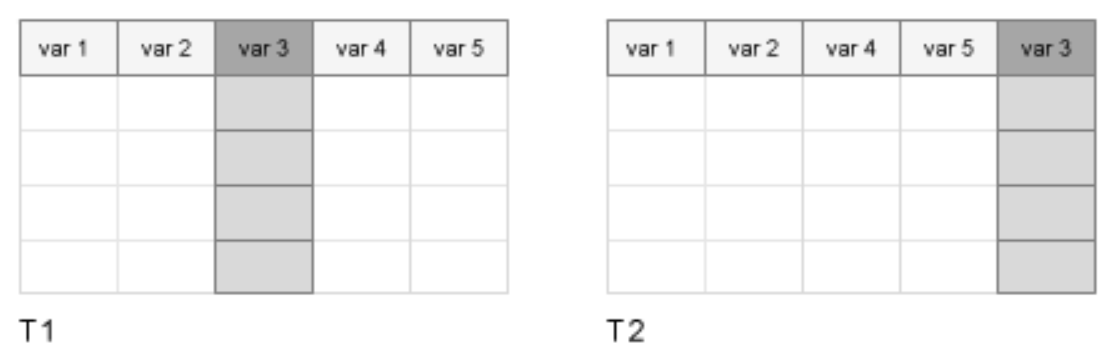

*Tomado de *[*MathWorks: *`movevars`](https://www.mathworks.com/help/matlab/ref/table.movevars.html)*.*

`A continuación se muestra un ejemplo de esto.`

% Ingrese su código aquí :)

## Realizar cálculos con tablas

Hasta este momento se ha realizado diferentes ejercicios y ejemplos utilizando funciones para clases numéricas (enteros y decimales), cadenas y arreglos caracter, y para valores lógicos.

Entonces es posible reasignar a una variable la misma variable modificada (aplicando algún cálculo, función, etc.), o simplemente creando una variable a partir de otras variables.

% Ingrese su código aquí :)

#### Observación

La función `mean` es similar a la función `max` o `min`, sólo que en lugar de obtener el número máximo o mínimo, respectivamente, se obtendrá la media artimética, o promedio, por filas.

## Material adicional

- [Tablas](https://www.mathworks.com/help/matlab/tables.html)

- [Ventajas de usar tablas](https://www.mathworks.com/help/matlab/matlab_prog/advantages-of-using-tables.html)

- [Crear tablas y asignarles información](https://www.mathworks.com/help/matlab/matlab_prog/create-a-table.html)

- [Acceder a información de una tabla](https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html)

- [Agregar, eliminar y reorganizar variables de tabla](https://www.mathworks.com/help/matlab/matlab_prog/add-and-delete-table-variables.html)

- [Cálculos en tablas](https://www.mathworks.com/help/matlab/matlab_prog/calculations-on-tables.html)

- [Modificar unidades, descripciones y nombres de variables de tabla](https://www.mathworks.com/help/matlab/matlab_prog/modify-units-descriptions-and-table-variable-names.html)

- [Conjuntos de datos de muestra](https://www.mathworks.com/help/stats/sample-data-sets.html)